# Lab2

## Objectives

### Model identification

- Parameter estimation

- Calibration & validation

Empirical model for reservoir inflows

- Linear AR model

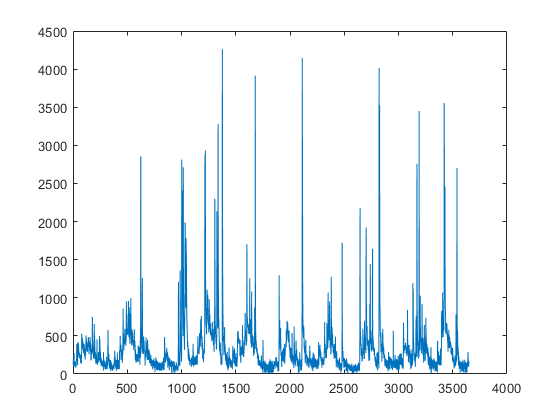

% Exercise 1 - Stationary statistics
data = load("data\Verbano_inflows_74_83_nb.txt");
% plot(data(:,2),data(:,1), '*')
plot(data)

N = length(data)

N = 3650

data_min = min(data)

data_min = 1.5000

data_max = max(data)

data_max = 4.2614e+03

data_range = range(data)

data_range = 4.2599e+03

data_mean = mean(data)

data_mean = 321.3367

data_var = var(data)

data_var = 1.2365e+05

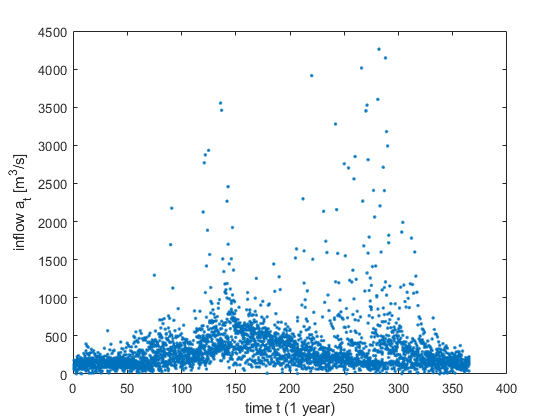

% Exercise 2 - Cyclostationary statistics

% Periodicity
T = 365;
tt = repmat([1:T]', N/T, 1);
figure;
plot(tt ,data ,'.' );
xlabel('time t (1 year)'); 
ylabel('inflow a_t [m^3/s]');

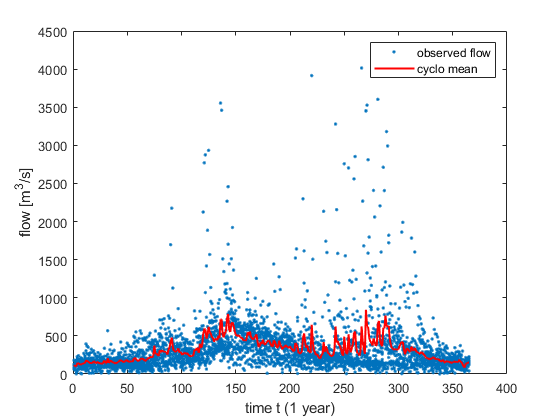

Q = reshape(data, T, 10);
% Cyclo-stationary mean
Cm = mean(Q,2); % Same as mean(Q')'
% Cyclo-stationary variance
Cv = var(Q')';
plot(tt, data, '.' );
hold on;
plot(Cm, 'r', 'LineWidth', 1.5); 
legend('observed flow', 'cyclo mean');
xlabel('time t (1 year)');
ylabel('flow [m^3/s]');

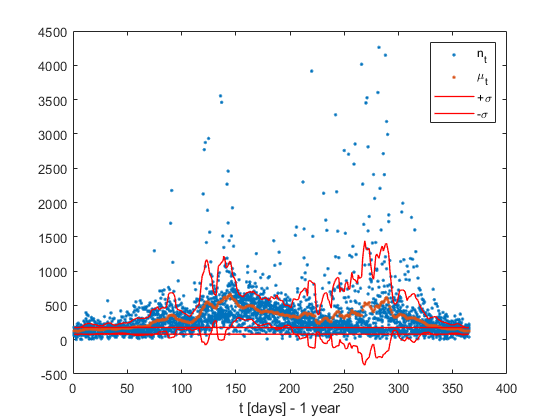

% Exercise 3 - Cyclostationary moving variance
T = 365;
f = 3;
% Moving Average
[mi, m] = moving_average(data, T, f);
% Moving variance
[ma_var2, s2] = moving_average((data - m).^2, T, f);
ma_var = ma_var2.^(1/2);
s = s2.^(1/2);

figure;
plot(tt, [data, m], '.');
xlabel('t [days] - 1 year');
hold on;
plot(tt, m + s, 'r', 'LineWidth',1);
plot(tt, m - s, 'r', 'LineWidth',1);
legend('n_t', '\mu_t', '+\sigma', '-\sigma');

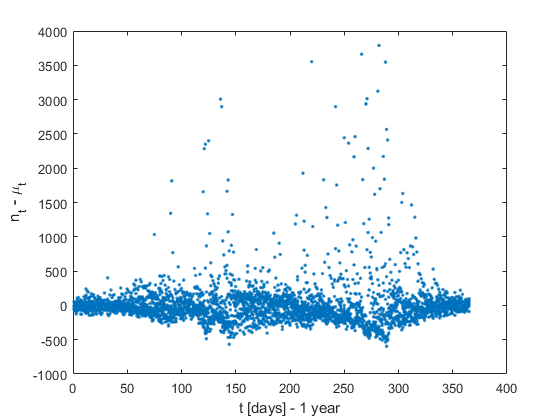

figure;
plot(tt, data - m, '.')
xlabel('t [days] - 1 year');
ylabel('n_t - \mu_t');

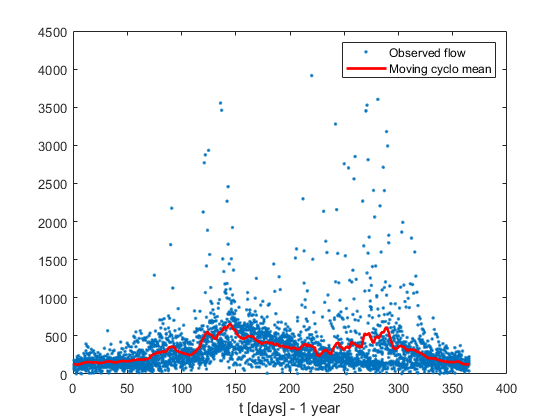

figure;
plot(tt, data, '.');
hold on;
plot([1 : T], mi, 'r', 'LineWidth',2);
legend('Observed flow', 'Moving cyclo mean');
xlabel('t [days] - 1 year');

% Exercise 4 - Param identification, linear model
data2 = load("data\storage_surface.txt");

y = data2(:,1);
x = data2(:,2);
N = length(x);

M = ones(size(data2));
M(:,1) = x;

theta = M\y;
a = theta(1);
b = theta(2);
lin_reg = a*x + b;

% Homework - Approximate power law model
% TODO: Check power law param estimation

lin_mse = (1/N)*sum((y-lin_reg).^2)

lin_mse = 8.7707e+10

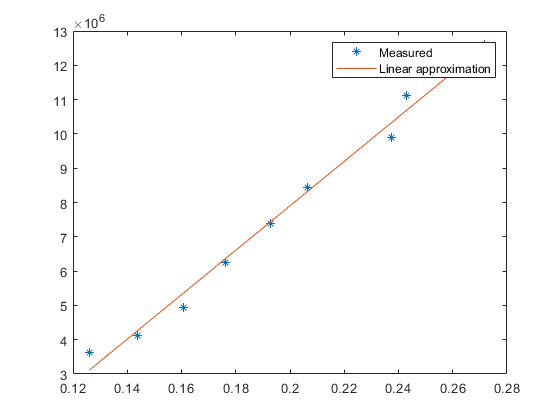

figure;
plot(x, y,'*');
hold on;
plot(x, lin_reg);
legend('Measured', 'Linear approximation');

% Exercise 5 - AR(1) estimation
% Deseasonalize
x = (data - m) ./ s;

% Param estimation - 1-step ahead
y = x(2:end);
M = x(1:end-1);
theta = M\y

theta = 0.7177

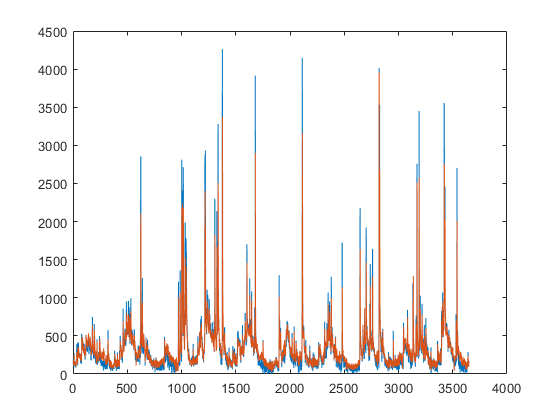

data_reg = M * theta;
data_reg = [x(1); data_reg];

% Seasonalized regressor
data_ar = data_reg .* s + m;
figure; plot([data, data_ar]);

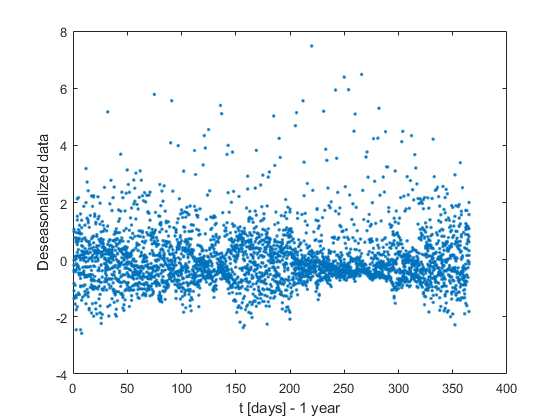


figure; 
plot(tt, x, '.');
xlabel('t [days] - 1 year');
ylabel('Deseasonalized data');

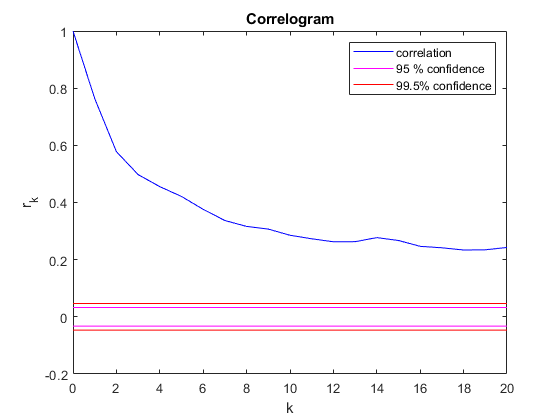

figure;
correlogram(data, data, 20);
xlabel('k');
ylabel('r_k');

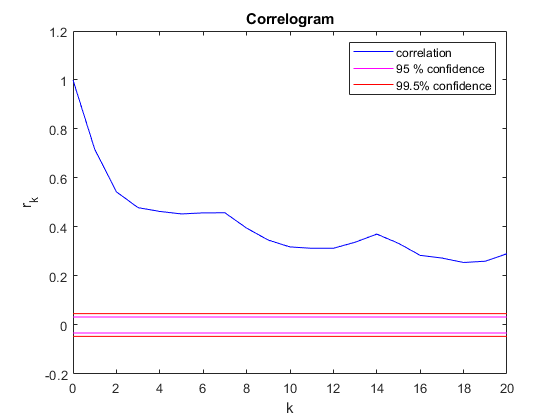

figure;
correlogram(x, x, 20);
xlabel('k');
ylabel('r_k');